# **Pluse Shaper**

% ************************************************************************
% Author: CONG LI
% Date Created: 2023
%
% This script is part of a course project for 
% Communication Systems: Theory and Measurement M
% at University of Bologna.
% ************************************************************************

PAM Signal Representation: The equation  describes how the PAM signal is constructed:The symbols are shown as discrete values like −1,−3,1,3-1, -3, 1, 3−1,−3,1,3, which are fed into the pulse shaper.The pulse shaper is responsible for converting discrete symbols into a continuous waveform. The purpose of pulse shaping is to generate a smooth signal that can be efficiently transmitted over a channel.The output x(t) is a continuous-time signal, which is a superposition of the pulses corresponding to the input symbols. This signal can then be transmitted over a communication channel. 

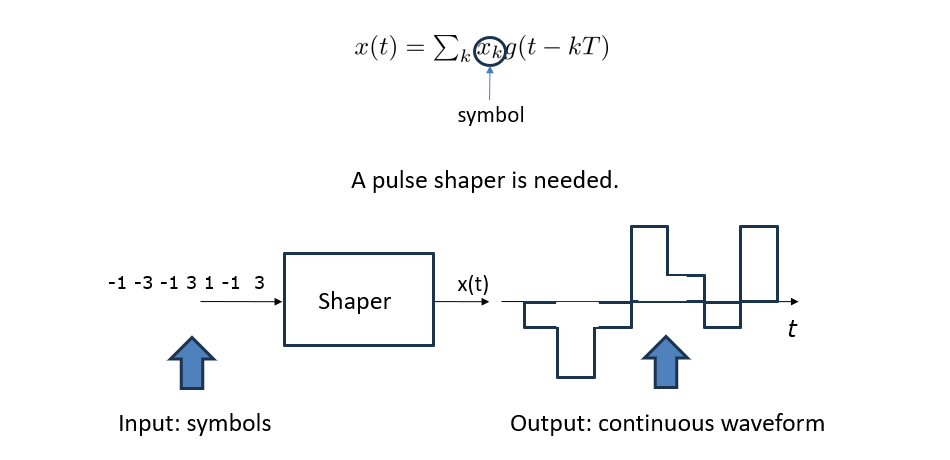

The following code segment defines a set of symbols representing complex numbers and initializes parameters for a pulse amplitude modulation (PAM) system, generating a modulated signal (x) and the corresponding pulse shape. Then plotting pulse shape and signals 

clear all
symbols=[1+j -1-j -1+j 1-j -1-j 1+j 1+j -1-j 1+j -1+j -1+j 1-j 1+j -1-j 1+j 1-j];
Nf=200; % number of samples of the basic pulse
nsps=10; % number of samples of the PAM signal in a symbol time
rolloff=0.2; % rool-off factor for the root raised cosine pulse
pulsetype="RECT"; % choose the pulse type by uncommenting the corresponding line

**PAMmodulator rectangular pluse**

The following code segment chooses a rectangular pluse as a basic pluse, mapping from bits to symbols by convolution opeartion.

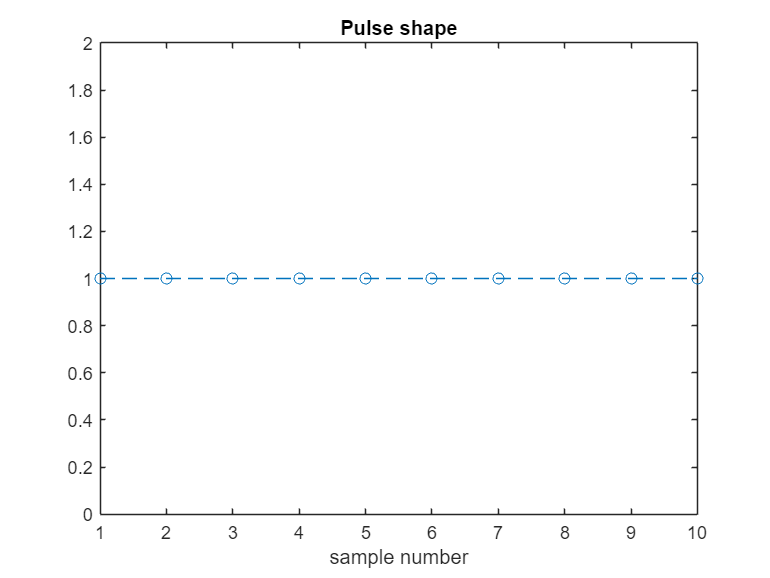

[x,h,Delay]=PAMmodulator_2023(symbols,nsps,Nf,pulsetype,rolloff);
plot(h,'--o')
xlabel('sample number')
title('Pulse shape')

One time continuous waveform is represented by means of nsps=10 samplings with amplitude is 1.

figure
plot(real(x),'--o')
xlabel('sample number')
title('xI')
real(symbols)

ans =      1    -1    -1     1    -1     1     1    -1     1    -1    -1     1     1    -1     1     1


axis([1 length(x) 1.1*min(real(x)) 1.1*max(real(x))])

This picture shows the result of PAM signal with rectangular pulses corresopend to in phase components of signals.

figure
plot(imag(x),'--o')
xlabel('sample number')
title('xQ')
imag(symbols)

ans =      1    -1     1    -1    -1     1     1    -1     1     1     1    -1     1    -1     1    -1


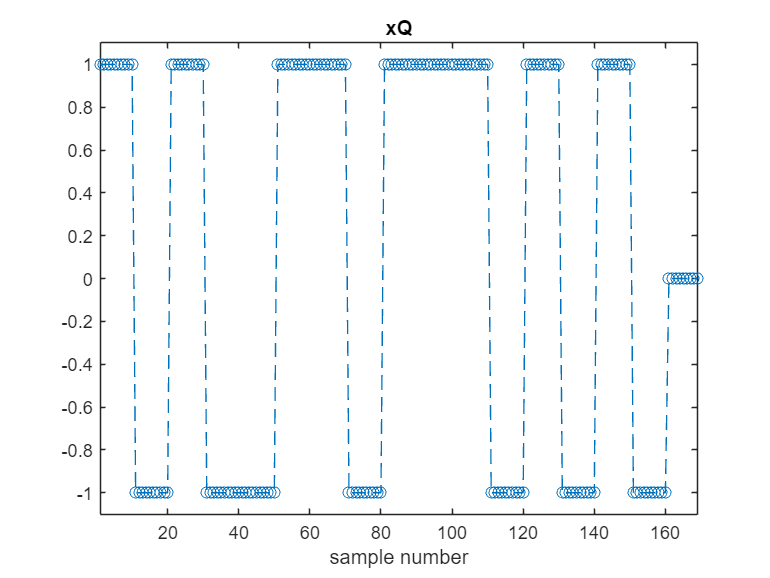

axis([1 length(x) 1.1*min(imag(x)) 1.1*max(imag(x))])

This picture shows the result of PAM signal with rectangular pulses corresopend to in *quadrature* components of signals.

**PAMmodulator (rootraisedcosine pluse)**

Similar to the previous code, the following code chooses rootraisdconsine pluse shape as basic pluse and compared with different rolloff.

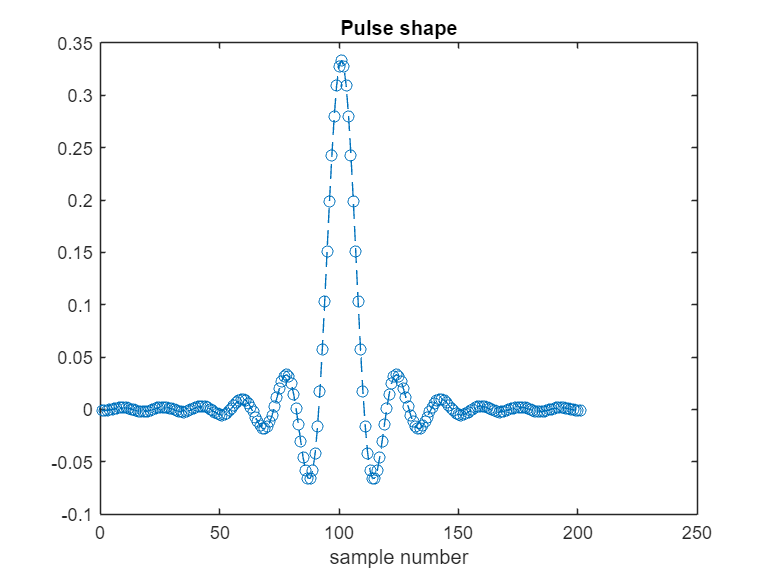

pulsetype="ROOTRAISEDCOSINE"; % choose the pulse type by uncommenting the corresponding line
[x,h,Delay]=PAMmodulator_2023(symbols,nsps,Nf,pulsetype,rolloff);
[x1,h1,Delay]=PAMmodulator_2023(symbols,nsps,Nf,pulsetype,rolloff*2);
[x2,h2,Delay]=PAMmodulator_2023(symbols,nsps,Nf,pulsetype,rolloff*4);

figure
plot(h,'--o')
xlabel('sample number')
title('Pulse shape')

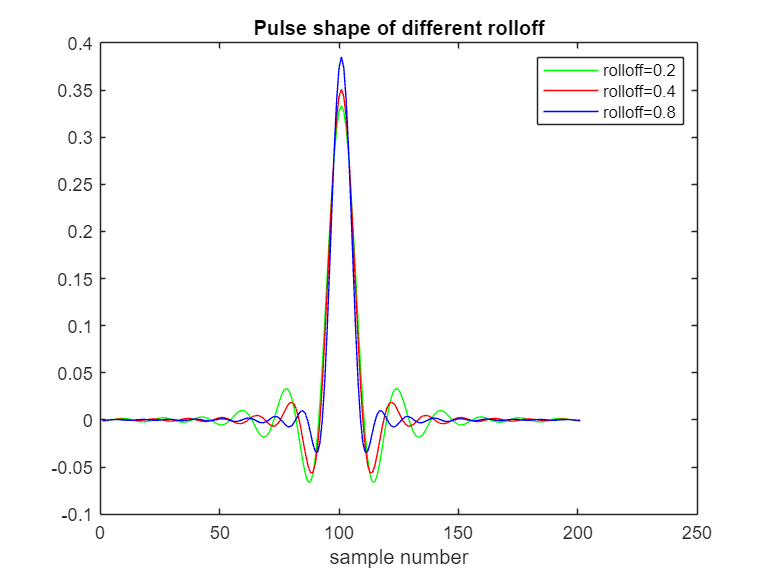

figure
plot(h,'b')

hold on
plot(h1,'r')
hold on
plot(h2,'g')
legend('rolloff=0.2','rolloff=0.4','rolloff=0.8')
xlabel('sample number')
title('Pulse shape of different rolloff')


imag(symbols)

ans =      1    -1     1    -1    -1     1     1    -1     1     1     1    -1     1    -1     1    -1


Comparing to three different rolloff It can be concluded the larger rolloff the larger, the greater the amplitude of the signal and the faster the attenuation,

figure
plot(real(x),'--o')
xlabel('sample number')
title('xI rolloff=0.2')
real(symbols)

ans =      1    -1    -1     1    -1     1     1    -1     1    -1    -1     1     1    -1     1     1


axis([1 length(x) 1.1*min(real(x)) 1.1*max(real(x))])
figure
plot(real(x),'b')
hold on
plot(real(x1),'r')
hold on
plot(real(x2),'g')
legend('rolloff=0.2','rolloff=0.4','rolloff=0.8')
xlabel('sample number')
title('xI of different rolloff')
real(symbols)

ans =      1    -1    -1     1    -1     1     1    -1     1    -1    -1     1     1    -1     1     1


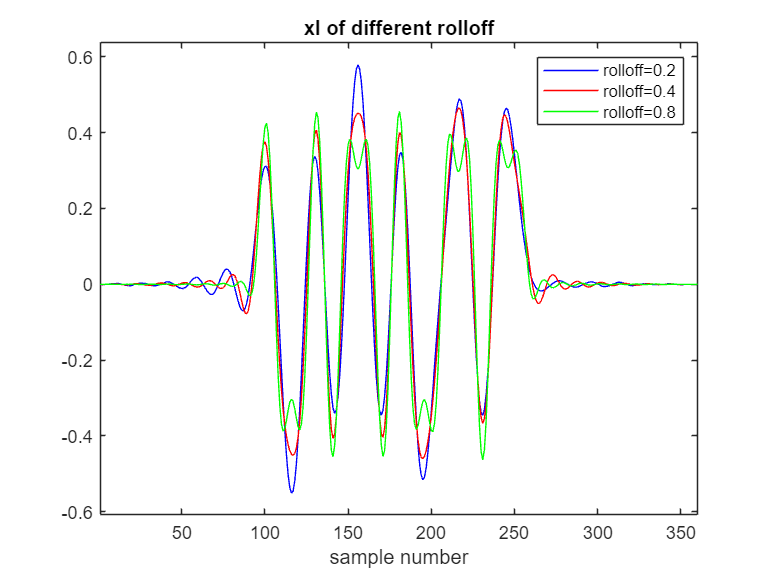

axis([1 length(x) 1.1*min(real(x)) 1.1*max(real(x))])

axis([1 length(x) 1.1*min(real(x)) 1.1*max(real(x))])

figure
plot(imag(x),'--o')
xlabel('sample number')
title('xQ rolloff=0.2')
imag(symbols)

ans =      1    -1     1    -1    -1     1     1    -1     1     1     1    -1     1    -1     1    -1


axis([1 length(x) 1.1*min(imag(x)) 1.1*max(imag(x))])

imag(symbols)

ans =      1    -1     1    -1    -1     1     1    -1     1     1     1    -1     1    -1     1    -1


figure
plot(imag(x),'k')
hold on
plot(imag(x1),'r')
hold on
plot(imag(x2),'g')
legend('rolloff=0.2','rolloff=0.4','rolloff=0.8')
xlabel('sample number')
title('xQ of different rolloff')
imag(symbols)

ans =      1    -1     1    -1    -1     1     1    -1     1     1     1    -1     1    -1     1    -1


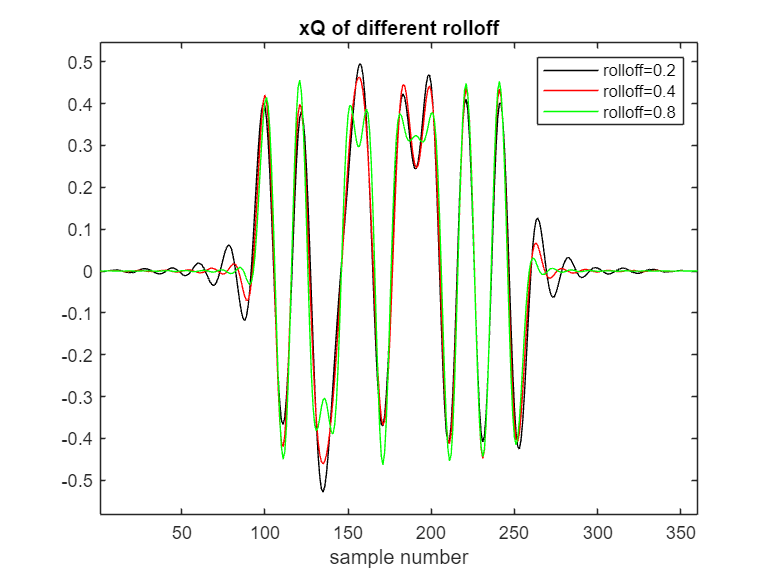

axis([1 length(x) 1.1*min(imag(x)) 1.1*max(imag(x))])


axis([1 length(x) 1.1*min(imag(x)) 1.1*max(imag(x))])

Comparing to symbols sequence with different rolloff, It can be concluded the larger rolloff, the more the waveform tends to be in a rectangular pluse, and the smaller rolloff, the more waveform tends to be in a sinc pluse.